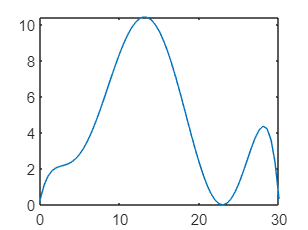

%% a) plot the polynomial
x=0:0.5:30;

%define the coefficients using a vector
p=[ -4.893904*10^-6, 4.08558*10^-4, -1.22598*10^-2, 0.157692, -0.831185, 2.01961, 0.262164    ];
%compute the function using polyval, and plot
y=polyval(p,x);
figure
plot(x,y)
hold on


%% b) obtain the exact integral solution from 0 to 30
% Use either polyint of the polynomial, or
% make the coefficients yourself by manual integration and then use polyval
x1=30;
%using polyint and polyval
pe=   polyint(p)   %gives the polynomial coefficients of the exact integral

pe =   -0.000000699129143   0.000068093000000  -0.002451960000000   0.039423000000000  -0.277061666666667   1.009805000000000   0.262164000000000                   0


Iexact=   polyval(pe, x1)     %evaluates the integral from 0 to 30

Iexact =      1.358690657142791e+02

%Or using coefficients
pa=[-4.893904e-6/7, 4.08558e-4/6, -1.22598e-2/5, 0.157692/4, -0.831185/3, 2.01961/2, 0.262164,0]

pa =   -0.000000699129143   0.000068093000000  -0.002451960000000   0.039423000000000  -0.277061666666667   1.009805000000000   0.262164000000000                   0


Iexact2=polyval(pa, 30)

Iexact2 =      1.358690657142791e+02



%% c) trapezoidal rule 
xt1=linspace( 0, 30, 5    )%4 segments

xt1 =                    0   7.500000000000000  15.000000000000000  22.500000000000000  30.000000000000000


xt2=linspace( 0, 30, 7    )%6 segments

xt2 =      0     5    10    15    20    25    30


yt1=polyval(  p, xt1   );
yt2=polyval(  p, xt2   );
Itrap4=trapz( xt1, yt1  )

Itrap4 =      1.138013523632832e+02

Itrap6=trapz( xt2, yt2  )

Itrap6 =      1.234389300000035e+02

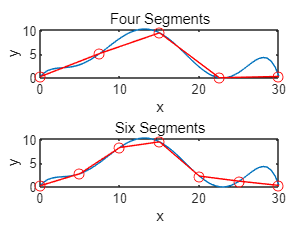


%% plotting
subplot(2,1,1); plot(x,y); hold on
plot(xt1,yt1,'ro-')%4 segments
xlabel('x');ylabel('y');title('Four Segments');

subplot(2,1,2); plot(x,y);hold on %6 segments
plot(xt2,yt2,'ro-')
xlabel('x');ylabel('y');title('Six Segments');

etrap4=abs(Iexact - Itrap4)/Iexact*100%

etrap4 =   16.241896737114821

etrap6=(Iexact - Itrap6)/Iexact*100%

etrap6 =    9.148613519147226